clear all
close all
load('Benchmark_EEG_small')

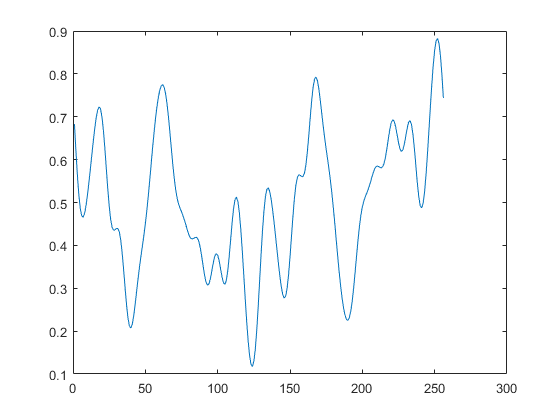

rng(1);
Siz = size(data.u,1); % #participants 
Miz = size(data.u,2); % #realizations
Niz = size(data.u,3); % #samples

partici =  2;

for j =1:Miz
in1(:,j) = 0.5+squeeze(data.u(partici,j,:)/6);
in1d(:,j) = 0.5+diff(in1(:,j))*6;
out1(:,j) = 0.5+squeeze(data.y(partici,j,:)/6);
out1d(:,j) = 0.5+diff(out1(:,j)*1.5);
end

plot(in1(:,1))

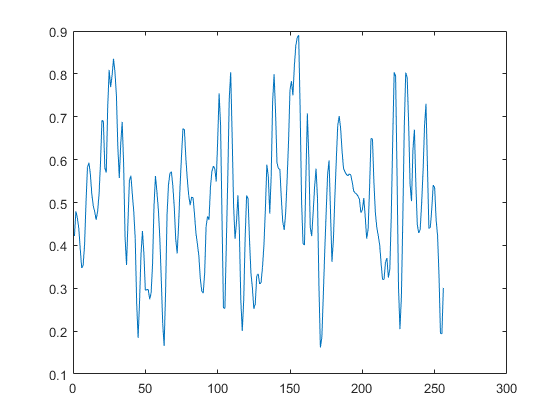

plot(out1(:,1))

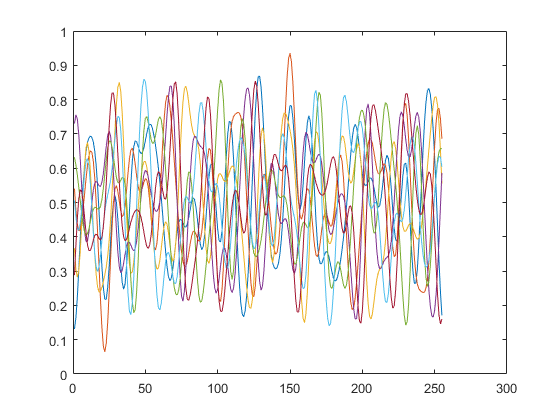

plot(in1d)

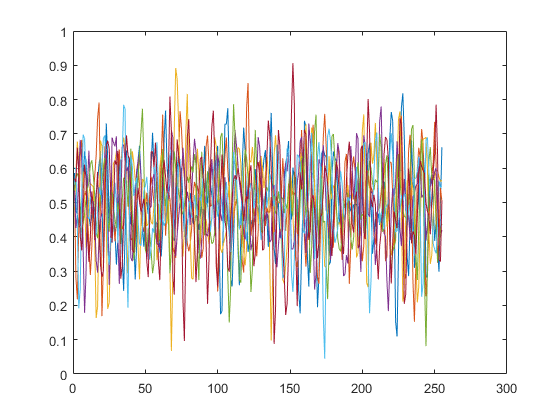

plot(out1d)


begini = 32;

SH=3  ;
SU=0  ;
d1=0  ;
d2=0  ;
begini-d1-3-SH

ans = 26


% VAF LOOP BEGIN -----
% for ind = 1:1 %Miz
 ind = 1

ind = 1

vali = ind;
traini = setdiff([1:Miz],vali);

u1 = in1(begini-d1-SU:end-d1-SU,traini);
u2 = in1(begini-d1-1-SU:end-1-d1-SU,traini);
u3 = in1(begini-d1-3-SU:end-3-d1-SU,traini);
u4 = in1(begini-d1-7-SU:end-7-d1-SU,traini);
u5 = in1(begini-d1-6-SU:end-6-d1-SU,traini);
u6 = in1(begini-d1-8-SU:end-8-d1-SU,traini);

v1 = in1d(begini-d2-SU-1:end-d2-SU,traini);
v2 = in1d(begini-d2-1-SU-1:end-1-d2-SU,traini);
v3 = in1d(begini-d2-2-SU-1:end-2-d2-SU,traini);
v4 = in1d(begini-d2-3-SU-1:end-3-d2-SU,traini);

y1 = out1(begini-SH:end-SH,traini);
y2 = out1(begini-1-SH:end-1-SH,traini);
y3 = out1(begini-17-SH:end-17-SH,traini);
y4 = out1(begini-25-SH:end-25-SH,traini);
y5 = out1(begini-21-SH:end-21-SH,traini);
y6 = out1(begini-28-SH:end-28-SH,traini);

dy1 = out1d(begini-SH-1:end-SH,traini);
dy2 = out1d(begini-2-SH-1:end-2-SH,traini);
dy3 = out1d(begini-3-SH-1:end-3-SH,traini);
dy4 = out1d(begini-7-SH-1:end-7-SH,traini);
dy5 = out1d(begini-11-SH-1:end-11-SH,traini);

y = out1(begini:end,traini);
dy = out1d(begini-1:end,traini);

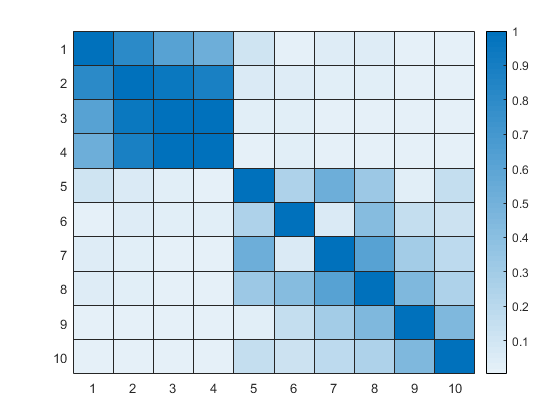

ans =   HeatmapChart with properties:

        XData: {10×1 cell}
        YData: {10×1 cell}
    ColorData: [10×10 double]

  Show all properties



zetacl = reshape(y,[],1);

u1 = reshape(u1,[],1);
u2 = reshape(u2,[],1);
u3 = reshape(u3,[],1);
u4 = reshape(u4,[],1);
u5 = reshape(u5,[],1);
u6 = reshape(u6,[],1);

v1 = reshape(v1,[],1);
v2 = reshape(v2,[],1);
v3 = reshape(v3,[],1);
v4 = reshape(v4,[],1);

y1 = reshape(y1,[],1);
y2 = reshape(y2,[],1);
y3 = reshape(y3,[],1);
y4 = reshape(y4,[],1);
y5 = reshape(y5,[],1);
y6 = reshape(y6,[],1);

dy1 = reshape(dy1,[],1);
dy2 = reshape(dy2,[],1);
dy3 = reshape(dy3,[],1);
dy4 = reshape(dy4,[],1);
dy5 = reshape(dy5,[],1);
% featurezcl= [v4 v3 v2 v1 u6 u5 u4 u3 u2 u1 y1 y2 y3 y4 y5];

% featurezcl= [v3 v2 v1 u3 u2 u1 y1 y2 y3 y4];

zetacl = reshape(dy,[],1);

featurezcl= [u4 u3 u2 u1 y1 dy1 dy2 dy3 dy4 dy5];

heatmap(abs(corr(featurezcl)))

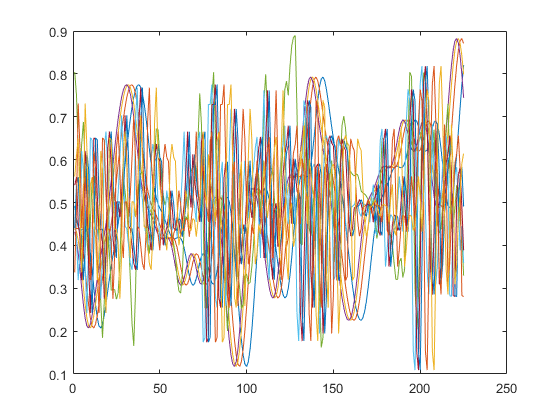


zetanoise = zetacl +0.001*rand(size(zetacl))-0.0005;

featureznoise = featurezcl ;% + 0.1*rand(size(featurezcl))-0.05;

featurez = [featurezcl ;featureznoise];

zeta = [zetacl ;zetanoise];
% min(featurez);

featurez = featurezcl;
zeta = zetacl;

u1t = in1(begini-d1-SU:end-d1-SU,vali);
u2t = in1(begini-d1-1-SU:end-1-d1-SU,vali);
u3t = in1(begini-d1-3-SU:end-3-d1-SU,vali);
u4t = in1(begini-d1-7-SU:end-7-d1-SU,vali);
u5t = in1(begini-d1-6-SU:end-6-d1-SU,vali);
u6t = in1(begini-d1-8-SU:end-8-d1-SU,vali);

v1t = in1d(begini-d2-SU-1:end-d2-SU,vali);
v2t = in1d(begini-d2-1-SU-1:end-1-d2-SU,vali);
v3t = in1d(begini-d2-2-SU-1:end-2-d2-SU,vali);
v4t = in1d(begini-d2-3-SU-1:end-3-d2-SU,vali);

y1t = out1(begini-SH:end-SH,vali);
y2t = out1(begini-1-SH:end-1-SH,vali);
y3t = out1(begini-17-SH:end-17-SH,vali);
y4t = out1(begini-25-SH:end-25-SH,vali);
y5t = out1(begini-21-SH:end-21-SH,vali);
y6t = out1(begini-28-SH:end-28-SH,vali);

dy1t = out1d(begini-SH-1:end-SH,vali);
dy2t = out1d(begini-2-SH-1:end-2-SH,vali);
dy3t = out1d(begini-3-SH-1:end-3-SH,vali);
dy4t = out1d(begini-7-SH-1:end-7-SH,vali);
dy5t = out1d(begini-11-SH-1:end-11-SH,vali);

yt = out1(begini:end,vali);
dyt = out1d(begini-1:end,vali);
% tfeaturez= [v4t v3t v2t v1t u6t u5t u4t u3t u2t u1t y1t y2t y3t y4t y5t];

tfeaturez= [u4t u3t u2t u1t y1t y2t y3t y4t];

tlabels = yt;


tfeaturez= [u4t u3t u2t u1t y1t dy1t dy2t dy3t dy4t dy5t];
tlabels = dyt;
% 
% tfeaturez = featurezcl;
% tlabels = zetacl;
refer = tlabels;


featurez(featurez<0)=0;
featurez(featurez>1)=1;
plot(tfeaturez);

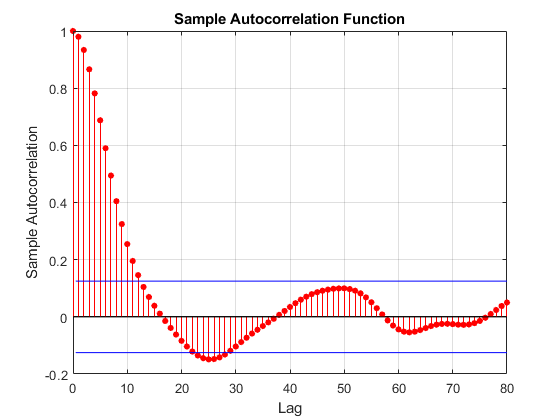

figure
autocorr(in1(:,1),80)

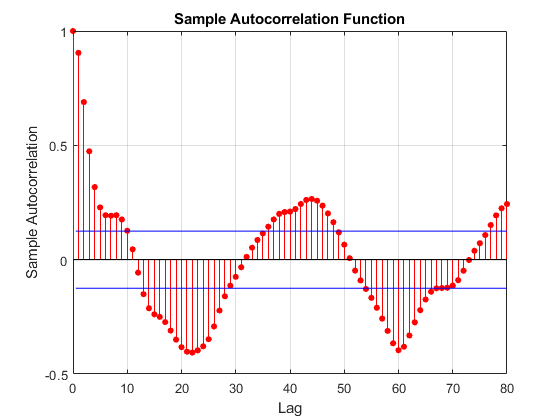

autocorr((out1(:,4)),80)

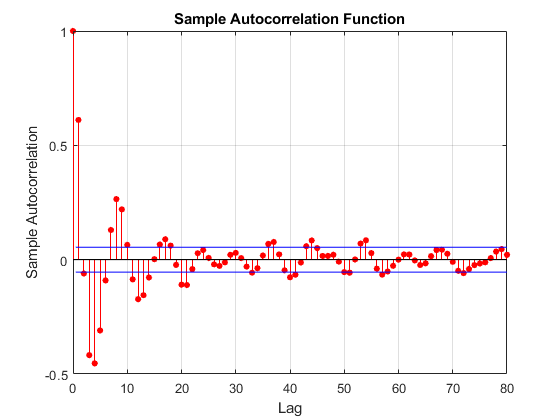

autocorr((zeta),80)

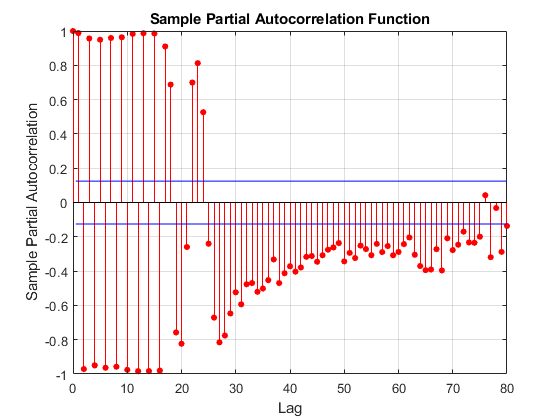


parcorr((in1(:,1)),80)

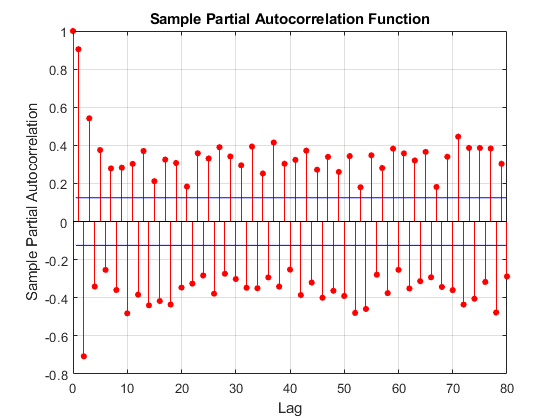

parcorr((out1(:,4)),80)

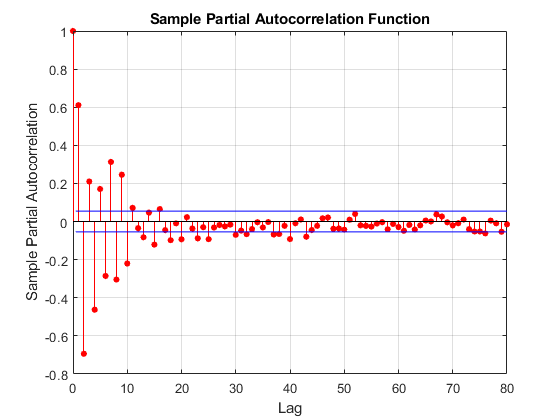

parcorr((zeta),80)

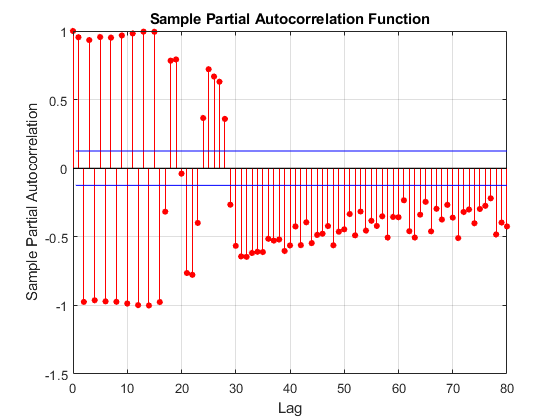



parcorr(diff(in1(:,4)),80)

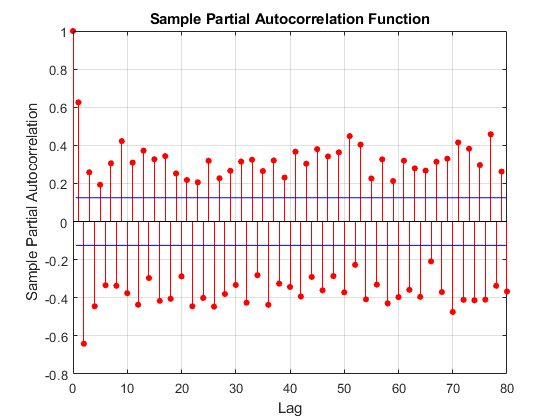

parcorr(diff(out1(:,4)),80)

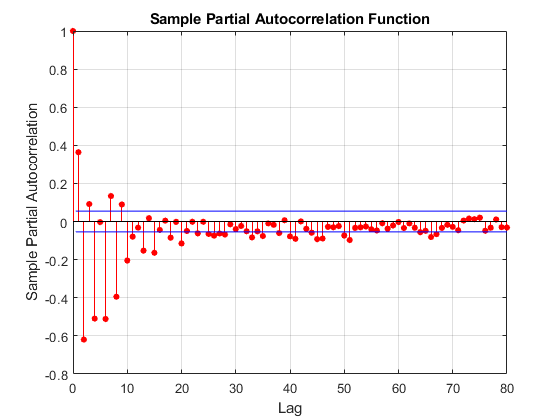

parcorr(diff(zeta),80)

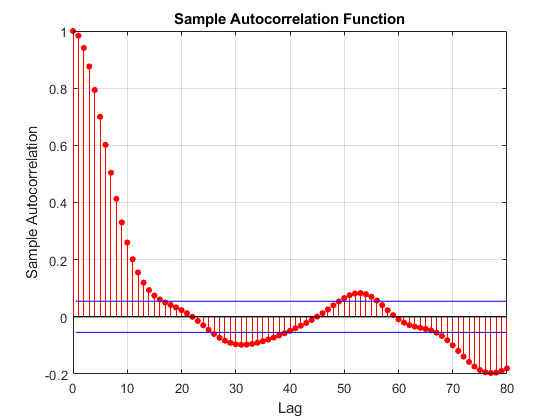


autocorr(u1,80)

% figure;hold on;
% plot(featurez(1:100,end-4:end-3))
% 
% plot(zeta(1:100))
% hold off

[N, d]=size(featurez); 

nn = 2;  %degree B-spline
knotintervals = 2;
nnn= knotintervals+nn;

bs = bspline([0:nn+1]);
M = flipud(bs.coefs)';

knotdist = 1/knotintervals;

indexes = floor(featurez/knotdist)+1;
indexes(indexes>knotintervals)= knotintervals;

% plot(indexes(:,5:8));

inputs = (featurez/knotdist)-indexes+1;
for i=1:d
bn = inputs(:,i).^[nn:-1:0]*M;

u{i} = zeros(N,nnn);
for ii=1:N
   u{i}(ii,indexes(ii,i):indexes(ii,i)+nn) = bn(ii,:);
end
end



Pcount = (nnn)^d
% gamma=((N/Pcount^4))
% gamma=0

R = nnn^2;
R=15;
r=R*ones(1,d+1);

% %  r(d-1)=nnn^2;
r(1) = 1;   r(d+1)=1;
r(2)=nnn;  r(d)=nnn;
r(3)=2*nnn;  r(d-1)=2*nnn;
r(4)=3*nnn;  r(d-2)=3*nnn;
% r(5)=3*nnn+1;  r(d-3)=3*nnn+1;
% r(6)=3*nnn+2;  r(d-4)=3*nnn+2;
% r(7)=3*nnn+3;  r(d-5)=3*nnn+3;
r(3)=nnn*2;  r(d-1)=nnn*2;
r(4)=12;  r(d-2)=12;


disp(r)
n=nnn*ones(1,d);

init=cell(1,d);
    for i=1:d
        init{i}.core=randn(r(i),n(i),r(i+1));
        init{i}.core=(init{i}.core/(norm(init{i}.core(:))));
        init{i}.r(1)=r(i);
        init{i}.n = n(i);
        init{i}.r(2)=r(i+1);
    end


   
    
% function TN=tencom(y,u,r,init,varargin)

% 2018, Ching-Yun KO

% N=size(u{1},1);
% d=size(u,2);                 

for i=1:d
    n(i)=size(u{i},2);
end
  

for i=1:d
    TN.core{i}=init{i}.core;
    TN.n(i,:)=[init{i}.r(1),init{i}.n,init{i}.r(2)];
end


Vp=cell(1,d);
Vm=cell(1,d);

Vm{1}=ones(N,1);
Vp{d}=ones(N,1);

% initialize right-orthonormal cores with prescribed TN ranks
for i=d:-1:2
    Vp{i-1}=dotkron(Vp{i},u{i})*reshape(permute(TN.core{i},[3 2 1]),[r(i+1)*n(i),r(i)]); 
end

difforder=2;
P = diff(eye(nnn),difforder);
PP = P'*P;

res1=[];
res2=[];
MAXITR =  2*d;
bb=1
itr=1;                          % counts number of iterations
ltr=1;                          % flag that checks whether we sweep left to right
sweepindex=1;                   % index that indicates which TT core will be updated

gamma=0.1
% gamma=1*10^-2;
 tic

% while itr<2 || ((e(itr) < e(itr-1)) && (itr < MAXITR) && e(itr) > THRESHOLD)
while itr<2 ||  (itr < MAXITR )
%     ---------------------updateTT-----------------;
        
nselect = floor(((itr+1)/MAXITR)^4*(N));
dataselect = randperm((N),nselect);
dataselect = 1:N;
    %         % first construct the linear subsystem matrix
        A=dotkron(Vm{sweepindex}(dataselect,:),u{sweepindex}(dataselect,:),Vp{sweepindex}(dataselect,:));
%         g=pinv(A'*A)*(A'*y(dataselect,:));
     
%         -------------------difference penalty 

        for j=1:d
        Csize = TN.n(j,:);
        
        Dm = reshape(permute(TN.core{j}, [2 1 3]), [Csize(2) Csize(1)*Csize(3)]);
        mDDm = reshape(Dm'*Dm, [Csize(1) Csize(3) Csize(1) Csize(3)]);
        DD{j} = reshape(permute(mDDm,[1 3 2 4]), [Csize(1)*Csize(1) Csize(3)*Csize(3)]);
        PD = P*Dm;
        DPPD = reshape(PD'*PD, [Csize(1) Csize(3) Csize(1) Csize(3)]);
        DWD{j} = reshape(permute(DPPD,[1 3 2 4]), [Csize(1)*Csize(1) Csize(3)*Csize(3)]);
        eyez{j}= reshape(eye(Csize(1)), [Csize(1)^2 1]);
        eyep{j}= reshape(eye(Csize(2)), [Csize(2)^2 1]);
        end
        eyez{d+1}=1;
        
        for p= 1:d
            Dsize = TN.n(sweepindex,:);   
                if sweepindex==p
                    D1 = eyez{sweepindex};
                    D2 = PP(:);
                    D3 = eyez{sweepindex+1};
                elseif sweepindex<p
                    D1 = eyez{sweepindex};  
                    D2 = eyep{sweepindex};   
                    D3= DWD{p}*eyez{p+1};           
                    for it=(p-1):-1:(sweepindex+1)               
                        D3 = DD{it}*D3;
                    end                               
                elseif sweepindex>p   
                    D1= eyez{p}'*DWD{p};
                    for it=(p+1):(sweepindex-1)               
                        D1 = D1*DD{it};
                    end
                    D1=D1';
                    D2 = eyep{sweepindex};   
                    D3= eyez{sweepindex+1}; 
                end
          
            WW = kron(D3, kron(D2, D1));
            Wtemp = permute(reshape(WW, [Dsize(1) Dsize(1) Dsize(2) Dsize(2) Dsize(3) Dsize(3)]), [1 3 5 2 4 6]);
            W{p} = reshape(Wtemp, [prod(Dsize) prod(Dsize)]); 
        end
        WWW = W{1};
        for s =2:d
            WWW = WWW + W{s};
        end
%         ----------------------- 
%         D = eye(r(sweepindex)*(n(sweepindex))*r(sweepindex+1));         
        AA = A'*A;
        bb = bb+1;
        
        lambda = sqrt(trace(AA)/trace(WWW));
        Tracez(bb) = trace(AA);
        g=pinv(AA + gamma*lambda*WWW)*(A'*zeta(dataselect,:));
            Wcez(bb) = trace(WWW);
        if ltr
            % left-to-right sweep, generate left orthogonal cores and update vk1
            TN.core{sweepindex}=reshape(g,[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            [Q,R]=qr(reshape(g,[r(sweepindex)*(n(sweepindex)),r(sweepindex+1)])); 
            TN.core{sweepindex}=reshape(Q(:,1:r(sweepindex+1)),[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            TN.core{sweepindex+1}=reshape(R(1:r(sweepindex+1),:)*reshape(TN.core{sweepindex+1},[r(sweepindex+1),(n(sweepindex+1))*r(sweepindex+2)]),[r(sweepindex+1),n(sweepindex+1),r(sweepindex+2)]);
            Vm{sweepindex+1}=dotkron(Vm{sweepindex},u{sweepindex})*reshape(TN.core{sweepindex},[r(sweepindex)*n(sweepindex),r(sweepindex+1)]); % N x r_{i}
        else
            % right-to-left sweep, generate right orthogonal cores and update vk2
            TN.core{sweepindex}=reshape(g,[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            [Q,R]=qr(reshape(g,[r(sweepindex),(n(sweepindex))*r(sweepindex+1)])'); 
            TN.core{sweepindex}=reshape(Q(:,1:r(sweepindex))',[r(sweepindex),n(sweepindex),r(sweepindex+1)]);
            TN.core{sweepindex-1}=reshape(reshape(TN.core{sweepindex-1},[r(sweepindex-1)*(n(sweepindex-1)),r(sweepindex)])*R(1:r(sweepindex),:)',[r(sweepindex-1),n(sweepindex-1),r(sweepindex)]);
            Vp{sweepindex-1}=dotkron(Vp{sweepindex},u{sweepindex})*reshape(permute(TN.core{sweepindex},[3 2 1]),[r(sweepindex+1)*n(sweepindex),r(sweepindex)]); % N x r_{i-1}    

        end
    
   %     ---------------------updatesweep-----------------; 
     
                if ltr
                    sweepindex=sweepindex+1;
                    if sweepindex== d                
                        ltr=0;
                        timer=toc;
                    end
                else
                    sweepindex=sweepindex-1;
                    if sweepindex== 1                
                        ltr=1;
                        timer=toc;
                    end
                end
    
    
        % only check residual after 1 half sweep
        if (sweepindex==d) || (sweepindex==1) % half a sweep
            
            res1(itr)=norm(A*g-zeta(dataselect,:))^2/(nselect); % check residual
            res2(itr)=1*(g'*g);
            res3(itr)=1*(g'*WWW*g);
           
            if (itr>4)
%                 if (res1(itr)<1) || (abs(res1(itr)-res1(itr-2))<1)
%                  disp(res1(itr))
%                  break;
%                  end
            end
            
            itr=itr+1; %update iteration
            
            disp(["iteration:" itr timer])
        end   
end  

plot(res1)
plot(res2)
plot(res3)

plot(Wcez)
plot(Tracez)
plot(Tracez./Wcez)


[Nt, dt]=size(tfeaturez);

indexes = floor(tfeaturez/knotdist)+1;
indexes(indexes>knotintervals)= knotintervals;

inputs = (tfeaturez/knotdist)-indexes+1;

for i=1:dt
bn = inputs(:,i).^[nn:-1:0]*M;

ut{i} = zeros(Nt,nnn);
for ii=1:Nt
   ut{i}(ii,indexes(ii,i):indexes(ii,i)+nn) = bn(ii,:);
end
end

% [N, d]=size(featurez);

output=zeros(Nt,1);

G = TN.core;

for i = 1:length(G)
Gsize = [Nt size(G{i},1)  size(G{i},3)];
tempz = reshape(ut{i}*unfold(G{i},2), Gsize);
V{i} = permute(tempz, [2 3 1]);
end


for jj=1:Nt   
f = (V{1});
f=1;
for i = 1:length(G)
f = f*V{i}(:,:,jj);
end
output(jj)=f';
end


tlabelz = tlabels;
outputsrt = output;


yminy1 = (outputsrt-0.5)/1.5

y_hat = (y1t(4:end) + yminy1(1:end-3))

figure
hold on
plot(y_hat)
plot(yt)
hold off


erboi = (y_hat-yt(1:end-3));

plot(erboi)
VAF(ind) = 1-var(erboi)/var(yt)


% end

% plot(VAF)


meanVAF = mean(VAF)

figure
hold on
plot(outputsrt)
plot(dyt)
% plot(refer)
hold off

[sortout,Iss]=sort(y_hat)
figure
hold on
plot(sortout)
plot(yt(Iss))
hold off

% plot(erboi)
pererror = sum(abs(erboi))/Nt
relerror = sum(abs(erboi)/sum(abs(refer)))
histogram((erboi)')

rerboi = (tlabelz-refer);
rpererror = sum(abs(rerboi))/Nt

FY = mag2db(abs(fft(outputsrt)));
FZ = mag2db(abs(fft(refer)));

figure;
hold on
plot(FY(1:floor(end/2)))
plot(FZ(1:floor(end/2)))
hold off

MSerr = immse(outputsrt,refer)

% ploterrcorr(erboi')
% autocorr(erboi')




% smoothed= smoothdata(output,'sgolay',20); 
% figure;
% hold on
% plot(output)
% plot(refer)
% % plot(smoothed)
% hold off

% Mdl = arima(3,4,3)
% EstMdl = estimate(Mdl,zeta)

% for i = 1:90
% testers(i,:) = forecast(EstMdl,3,y1t(i+50:i+140));
% end

% 
% figure
% hold on
% plot(y1t)
% plot(51:142,testers(:,3))
% hold off
